Reading calibration Data

filename_cali_real = '20111122_calibration_real.csv'; % Replace with your actual file name
filename_cali_imag = '20111122_calibration_imag.csv';
data_cali_real = csvread(filename_cali_real);   % Load the entire column
data_cali_imag = csvread(filename_cali_imag);
threshold = 1e-4;
data_cali_imag = 1i * data_cali_imag;
% data_cali_pre = data_cali_real + data_cali_imag
% data_cali_pre_ifft = ifft(data_cali_pre)
% data_pre_test = abs(data_cali_pre_ifft)
 data_cali_real_ifft = ifft(data_cali_real);
 data_cali_imag_ifft = ifft(data_cali_imag);
% data_cali_test = sqrt((data_cali_real_ifft.^2) + (data_cali_imag_ifft.^2))
% data_cali = sqrt((data_cali_real.^2) + (data_cali_imag.^2))

Extraction background data

filename_backg_real = '20111122_background_real.csv'; % Replace with your actual file name
filename_backg_imag = '20111122_background_imag.csv';
data_backg_real = csvread(filename_backg_real)  % Load the entire column

data_backg_real =          0
    0.0010
         0
         0
         0
         0
         0
         0
         0
         0


data_backg_imag = csvread(filename_backg_imag);
data_backg_imag = 1i * data_backg_imag

data_backg_imag =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0020i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


%data_backg = sqrt((data_backg_real.^2) + (data_backg_imag.^2))

Extracting projection data from object and calibrating

filename_real = '20111122_thin_rod_2mm_wire_real.csv'; % Replace with your actual file name
filename_imag = '20111122_thin_rod_2mm_wire_imag.csv';
data_real = csvread(filename_real);   % Load the entire column
data_imag = csvread(filename_imag);
data_imag = 1i * data_imag

data_imag =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0010i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


data_full = data_real + data_imag;
%removing noise
%preparing to subtract the calibration in time domain,
%or dividing in the frequency domain.
% Define parameters
total_samples = 566;
repetitions = 200;

% Initialize the 2D matrix to store the extracted points
extracted_matrix_full = zeros(total_samples, repetitions);

% Reshape the data into the desired matrix format
for rep = 1:repetitions
    start_index = (rep - 1) * total_samples+ 1;
    end_index = start_index + total_samples - 1;
    extracted_matrix_full(:, rep) = data_full(start_index:end_index);
end
extracted_matrix_full

extracted_matrix_full =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0



% test = ifft(extracted_matrix_full)
sum1=extracted_matrix_full(:,1)

sum1 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0010i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


plot(abs(sum1))
sum2=extracted_matrix_full(:,50)

sum2 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0010 + 0.0020i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


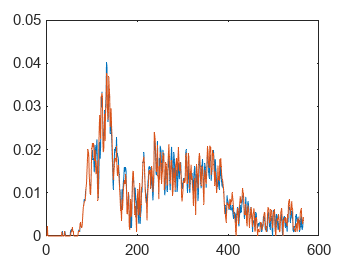

hold on
plot(abs(sum2))
hold off


% test_flipped = [test(283+1:566,:);test(1:283,:)]
% c = 3e8;
% start_freq = 300e3
% stop_freq = 8.4753e9
% fs=(stop_freq-start_freq)/566
% range_resolution = c / (2*(stop_freq-start_freq))
% range_bins = size(data_full_final_s21,1)
% ranges = ((0:range_bins-1)*range_resolution*(0.95./10))
% plot((abs(test_flipped(:,1))))
% hold on
% plot((abs(test_flipped(:,50))), color = 'r')
% plot((abs(test_flipped(:,100))), color = 'g')
% hold off


extracted_matrix_full_s21 = abs(extracted_matrix_full)

extracted_matrix_full_s21 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0014    0.0010         0         0         0         0         0         0         0    0.0010         0         0         0         0         0    0.0014         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0010    0.0010    0.0014    0.0010         0         0         0    0.0014         0         0    0.0010         0         0         0    0.0010    0.0010 

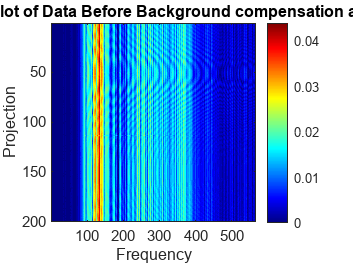

imagesc(extracted_matrix_full_s21');
colormap('jet');
xlabel('Frequency');
ylabel('Projection');
title('Spatial Frequency Plot of Data Before Background compensation and calibration');
colorbar;



extracted_matrix_full_noise_removed = extracted_matrix_full - (data_backg_real + data_backg_imag)

extracted_matrix_full_noise_removed =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0010 +

abs(extracted_matrix_full_noise_removed)

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010    0.0010    0.0010    0.0020    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0020    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0020         0    0.0010    0.0014    0.0010    0.0010    0.0010    0.0022    0.0010    0.0010    0.0014    0.0010    0.0010    0.0010    0.0014    0.0014    0.0010    0.0014   

% data_real_ifft = ifft(data_real_noise_removed);
% data_imag_ifft = ifft(data_imag_noise_removed);

%removing small transients
% data_full_ifft = zeros(566,repetitions);
% for bla =1:repetitions
%     for blabla =1:566
%         if( abs(extracted_matrix_full_noise_removed(blabla,bla))>1e-4 )
%             data_full_ifft(blabla,bla) = ifft(extracted_matrix_full_noise_removed(blabla,bla));
%         end
%     end
% end

data_full_ifft = ifft(extracted_matrix_full_noise_removed);

% data_real_prefinal = data_real_ifft - data_cali_real_ifft
% data_imag_prefinal = data_imag_ifft - data_cali_image_ifft
data_full_prefinal = data_full_ifft - (data_cali_real_ifft + data_cali_imag_ifft)

data_full_prefinal =    0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i   0.0015 - 0.0043i
  -0.0001 + 0.0007i  -0.0001

% data_real_final = fft(data_real_prefinal)
% data_imag_final = fft(data_imag_prefinal)

%REMOVING SMALL TRANSIENTS
 %data_full_final = zeros(566,200);
% for bla =1:repetitions
%     for blabla =1:566
%         if(abs(data_full_prefinal(blabla,bla))>1e-4)
%             data_full_final(blabla,bla) = fft(data_full_prefinal(blabla,bla));
%         end
%     end
% end

 data_full_final = fft(data_full_prefinal)

data_full_final =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0020 + 0.0000i  -0.0020 - 


data_full_final_s21 = abs(data_full_final)

data_full_final_s21 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0020    0.0020    0.0014    0.0030    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0030    0.0020    0.0020    0.0020    0.0020    0.0020    0.0014    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0030    0.0010    0.0014    0.0022    0.0020    0.0020    0.0020    0.0032    0.0020    0.0020    0.0022    0.0020    0.0020    0.0020    0.0022    0.0022    0.0

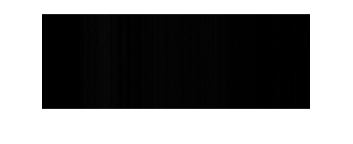

imshow(data_full_final_s21')

Now to try and plot this new s21 data with noise removed and uniform gain.

c = 3e8;
start_freq = 300e3

start_freq = 300000

stop_freq = 8.4753e9

stop_freq = 8.4753e+09

fs=(stop_freq-start_freq)/566

fs = 1.4973e+07


range_resolution = c / (2*(stop_freq-start_freq))

range_resolution = 0.0177

range_bins = size(data_full_final_s21,1)

range_bins = 566

ranges = ((0:range_bins-1)*range_resolution*(0.95./10))

ranges =          0    0.0017    0.0034    0.0050    0.0067    0.0084    0.0101    0.0118    0.0135    0.0151    0.0168    0.0185    0.0202    0.0219    0.0235    0.0252    0.0269    0.0286    0.0303    0.0319    0.0336    0.0353    0.0370    0.0387    0.0404    0.0420    0.0437    0.0454    0.0471    0.0488    0.0504    0.0521    0.0538    0.0555    0.0572    0.0588    0.0605    0.0622    0.0639    0.0656    0.0673    0.0689    0.0706    0.0723    0.0740    0.0757    0.0773    0.0790    0.0807    0.0824


times = (ranges / c)

times = 1.0e-08 *

         0    0.0006    0.0011    0.0017    0.0022    0.0028    0.0034    0.0039    0.0045    0.0050    0.0056    0.0062    0.0067    0.0073    0.0078    0.0084    0.0090    0.0095    0.0101    0.0106    0.0112    0.0118    0.0123    0.0129    0.0135    0.0140    0.0146    0.0151    0.0157    0.0163    0.0168    0.0174    0.0179    0.0185    0.0191    0.0196    0.0202    0.0207    0.0213    0.0219    0.0224    0.0230    0.0235    0.0241    0.0247    0.0252    0.0258    0.0263    0.0269    0.0275


data_full_prefinal_flipped = [data_full_prefinal(283+1:566,:);data_full_prefinal(1:283,:)]

data_full_prefinal_flipped =   -0.0001 - 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i
  -0.0001 - 0.0000i 

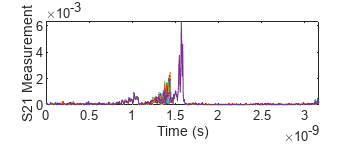

plot(times,abs(data_full_prefinal_flipped))
xlabel('Time (s)');
ylabel('S21 Measurement');

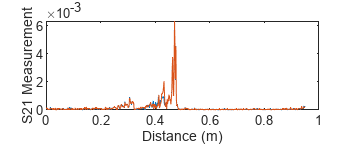


plot(ranges,abs(data_full_prefinal_flipped(:,1)))
hold on
plot(ranges,abs(data_full_prefinal_flipped(:,50)))
hold off
xlabel('Distance (m)');
ylabel('S21 Measurement');

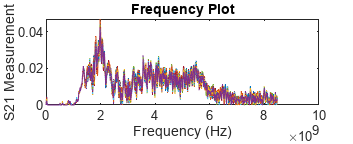



% ranges = (speed_of_light*time_axis)/2;
% plot(ranges, abs(data_full_prefinal'));
% xlabel('Range (m)');
% ylabel('S21 Measurement');

frequency_axis = linspace(start_freq, stop_freq, 566);
plot(frequency_axis, data_full_final_s21');
xlabel('Frequency (Hz)');
ylabel('S21 Measurement');
title('Frequency Plot');

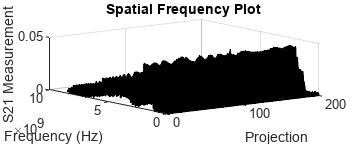


[projection_axis, sample_axis] = meshgrid(1:repetitions, frequency_axis);
surf(projection_axis,sample_axis,data_full_final_s21)
colormap('jet');
xlabel('Projection');
ylabel('Frequency (Hz)');
zlabel('S21 Measurement');
title('Spatial Frequency Plot');

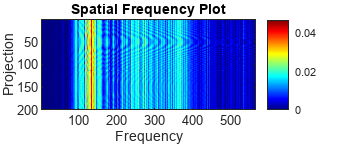


imagesc(data_full_final_s21')
colormap('jet');
xlabel('Frequency');
ylabel('Projection');
title('Spatial Frequency Plot');
colorbar;


%making a polar plot
theta = linspace(0,2*pi,repetitions)

theta =          0    0.0316    0.0631    0.0947    0.1263    0.1579    0.1894    0.2210    0.2526    0.2842    0.3157    0.3473    0.3789    0.4105    0.4420    0.4736    0.5052    0.5368    0.5683    0.5999    0.6315    0.6630    0.6946    0.7262    0.7578    0.7893    0.8209    0.8525    0.8841    0.9156    0.9472    0.9788    1.0104    1.0419    1.0735    1.1051    1.1367    1.1682    1.1998    1.2314    1.2630    1.2945    1.3261    1.3577    1.3892    1.4208    1.4524    1.4840    1.5155    1.5471


[T,R] = meshgrid(theta,frequency_axis)

T =          0    0.0316    0.0631    0.0947    0.1263    0.1579    0.1894    0.2210    0.2526    0.2842    0.3157    0.3473    0.3789    0.4105    0.4420    0.4736    0.5052    0.5368    0.5683    0.5999    0.6315    0.6630    0.6946    0.7262    0.7578    0.7893    0.8209    0.8525    0.8841    0.9156    0.9472    0.9788    1.0104    1.0419    1.0735    1.1051    1.1367    1.1682    1.1998    1.2314    1.2630    1.2945    1.3261    1.3577    1.3892    1.4208    1.4524    1.4840    1.5155    1.5471
         0    0.0316    0.0631    0.0947    0.1263    0.1579    0.1894    0.2210    0.2526    0.2842    0.3157    0.3473    0.3789    0.4105    0.4420    0.4736    0.5052    0.5368    0.5683    0.5999    0.6315    0.6630    0.6946    0.7262    0.7578    0.7893    0.8209    0.8525    0.8841    0.9156    0.9472    0.9788    1.0104    1.0419    1.0735    1.1051    1.1367    1.1682    1.1998    1.2314    1.2630    1.2945    1.3261    1.3577    1.3892    1.4208    1.4524    1.4840    1.5155    1

R = 1.0e+09 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    0.0153    

X = R .* cos(T);
Y = R .* sin(T);


%OBJECT POSITIONS AND DISTANCE CALCULATION
radar_position = [-70,0]

radar_position =    -70     0


object_positions = zeros(200, 2);
current_angle = zeros(200,1);
current_angle(1)=-pi;
for n = 1:repetitions
    %Try and recreate figure 3.1 with the x axis going vertically so
    %use sin for x and cos for y
    object_positions(n,1) = sin(current_angle(n)).*566;
    object_positions(n,2) = cos(current_angle(n)).*566;
    current_angle(n+1) = current_angle(n) + 0.01*pi;
end
current_angle

current_angle =    -3.1416
   -3.1102
   -3.0788
   -3.0473
   -3.0159
   -2.9845
   -2.9531
   -2.9217
   -2.8903
   -2.8588


object_positions

object_positions =    -0.0000 -566.0000
  -17.7785 -565.7207
  -35.5394 -564.8831
  -53.2653 -563.4881
  -70.9386 -561.5369
  -88.5419 -559.0316
 -106.0578 -555.9746
 -123.4691 -552.3689
 -140.7585 -548.2181
 -157.9090 -543.5262


image = zeros(1200,1200);
distance_object_to_radar = zeros(200,1);
for angle_idx = 1:repetitions
distance_object_to_radar(angle_idx) = sqrt((object_positions(angle_idx,1) - radar_position(1))^2 + (object_positions(angle_idx,2) - radar_position(2))^2);
x_start = object_positions(angle_idx,1);
y_start = object_positions(angle_idx,2);
angle_between_radar_object = acos(abs(object_positions(angle_idx,1)+70)/distance_object_to_radar(angle_idx));
    for freq_idx = 1:total_samples
        phase_shift = calculate_phase_shift(radar_position, frequency_axis(freq_idx), object_positions,angle_idx);
        y_pixel = round(freq_idx.*sin(current_angle(angle_idx)) + 600);
        x_pixel = round(freq_idx.*cos(current_angle(angle_idx)) +600); % this thing is not a integer
        image(x_pixel, y_pixel) = image(x_pixel, y_pixel) + (data_full_final(freq_idx, angle_idx) *10* exp(1j * phase_shift));
    end
end

image

image =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   

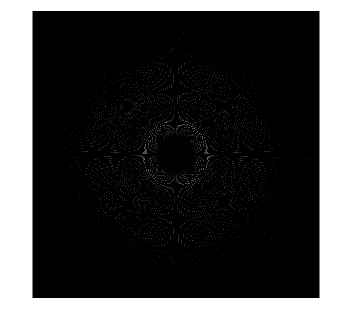

figure;
imshow(abs(image));

 function phase_shift = calculate_phase_shift(radar_position, frequency,position, i)
    % Constants
    speed_of_light = 3e8; % Speed of light in meters per second

    % Calculate distance between radar and position
    distance = sqrt((position(i) - radar_position(1))^2 + (position(i+1) - radar_position(2))^2);

    % Calculate wavelength
    wavelength = speed_of_light / frequency;

    % Calculate phase shift
    phase_shift = 2 * pi * (distance / wavelength);
 end

 